# Basics of preprocessing with SPM12

### SPM orientation

SPM12 is software written in Matlab. It's one of the most popular packages for analyzing neuroimaging data (the top 3 are SPM, FSL, and AFNI), and the developers at UCL have made it free for everyone to use.

You can do most everything in two ways: By clicking buttons in the graphic interface (GUI), and by coding. SPM functions generally start with spm_<something>.  The GUI is a great way to get oriented, but when you run analyses for research--often on many participants--and want to have a reproducible, tracked workflow, coding is essential.  We'll start with the GUI for now, but we'll include a few code examples along the way.

Starting SPM brings up the graphics windows:

 ___  ____  __  __                                            
/ __)(  _ \(  \/  )                                           
\__ \ )___/ )    (   Statistical Parametric Mapping           
(___/(__)  (_/\/\_)  SPM12 - http://www.fil.ion.ucl.ac.uk/spm/


SPM12: v6906                                       10:42:42 - 29/04/2021
Initialising SPM                        :                   ..Item 'Confounds', field 'strtype': Value must be a valid strtype.
Item 'Confounds', field 'val': Size mismatch (required [1  100], present [1  1]).
Item 'Condition Labels', field 'strtype': Value must be a valid strtype.
Item 'Condition Labels', field 'val': Size mismatch (required [1  100], present [1  1]).
Duplicate application tag in applications 'SPM' and 'SPM'.
Duplicate application tag in applications 'BasicIO' and 'BasicIO'.
.

.

.

.

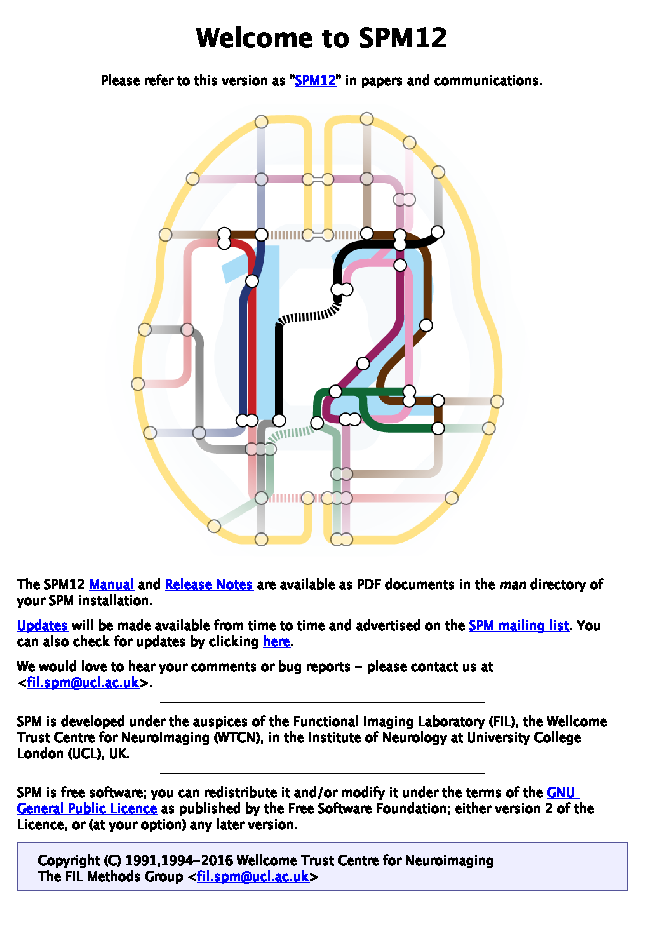

.

.

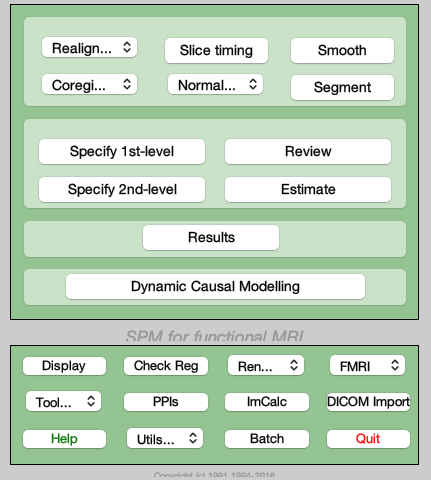

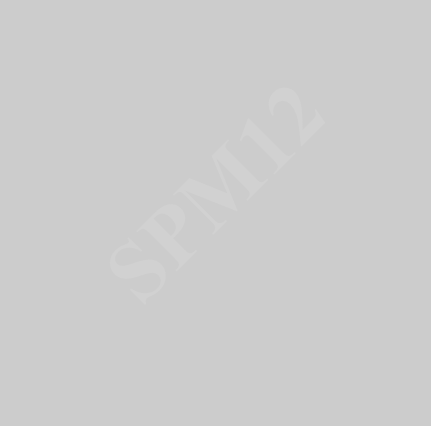

done

SPM present working directory:
	/Users/torwager/Dropbox (Dartmouth College)/COURSES/Courses_Dartmouth/2021_3_Spring_fMRI_Class/Labs_and_Lectures_for_Instructors/Labs_and_assignments/Lab_5/Pinel_data_sample_subject


spm fmri

#### Navigate to files

It's helpful to start in a folder with data in it, so you don't have to navigate extensively through the SPM file selection browser. 

pwd  % where am i now? (in terms of working directory, at least)

ans = '/Users/torwager/Dropbox (Dartmouth College)/COURSES/Courses_Dartmouth/2021_3_Spring_fMRI_Class/Labs_and_Lectures_for_Instructors/Labs_and_assignments/Lab_5/Pinel_data_sample_subject'

Use cd( ) to go to your sample subject directory. Drag and drop, or copy and paste the path from Terminal.

ls  % list files here

rp_sub-sid001567_task-pinel_acq-s1p2_run-03_bold.txt
rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii
rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz
sub-sid001567_task-pinel_acq-s1p2_run-03_bold.json
sub-sid001567_task-pinel_acq-s1p2_run-03_bold.mat
sub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz
sub-sid001567_task-pinel_acq-s1p2_run-03_events.tsv



**Unzip image files if needed**

Zipped (compressed) images most often have a .gz extension.

`rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz`

Use gunzip in Unix/Linux/Terminal, or from within Matlab, to unzip:

SPM12: spm_image (v6425)                           11:02:40 - 29/04/2021
Display rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii,1


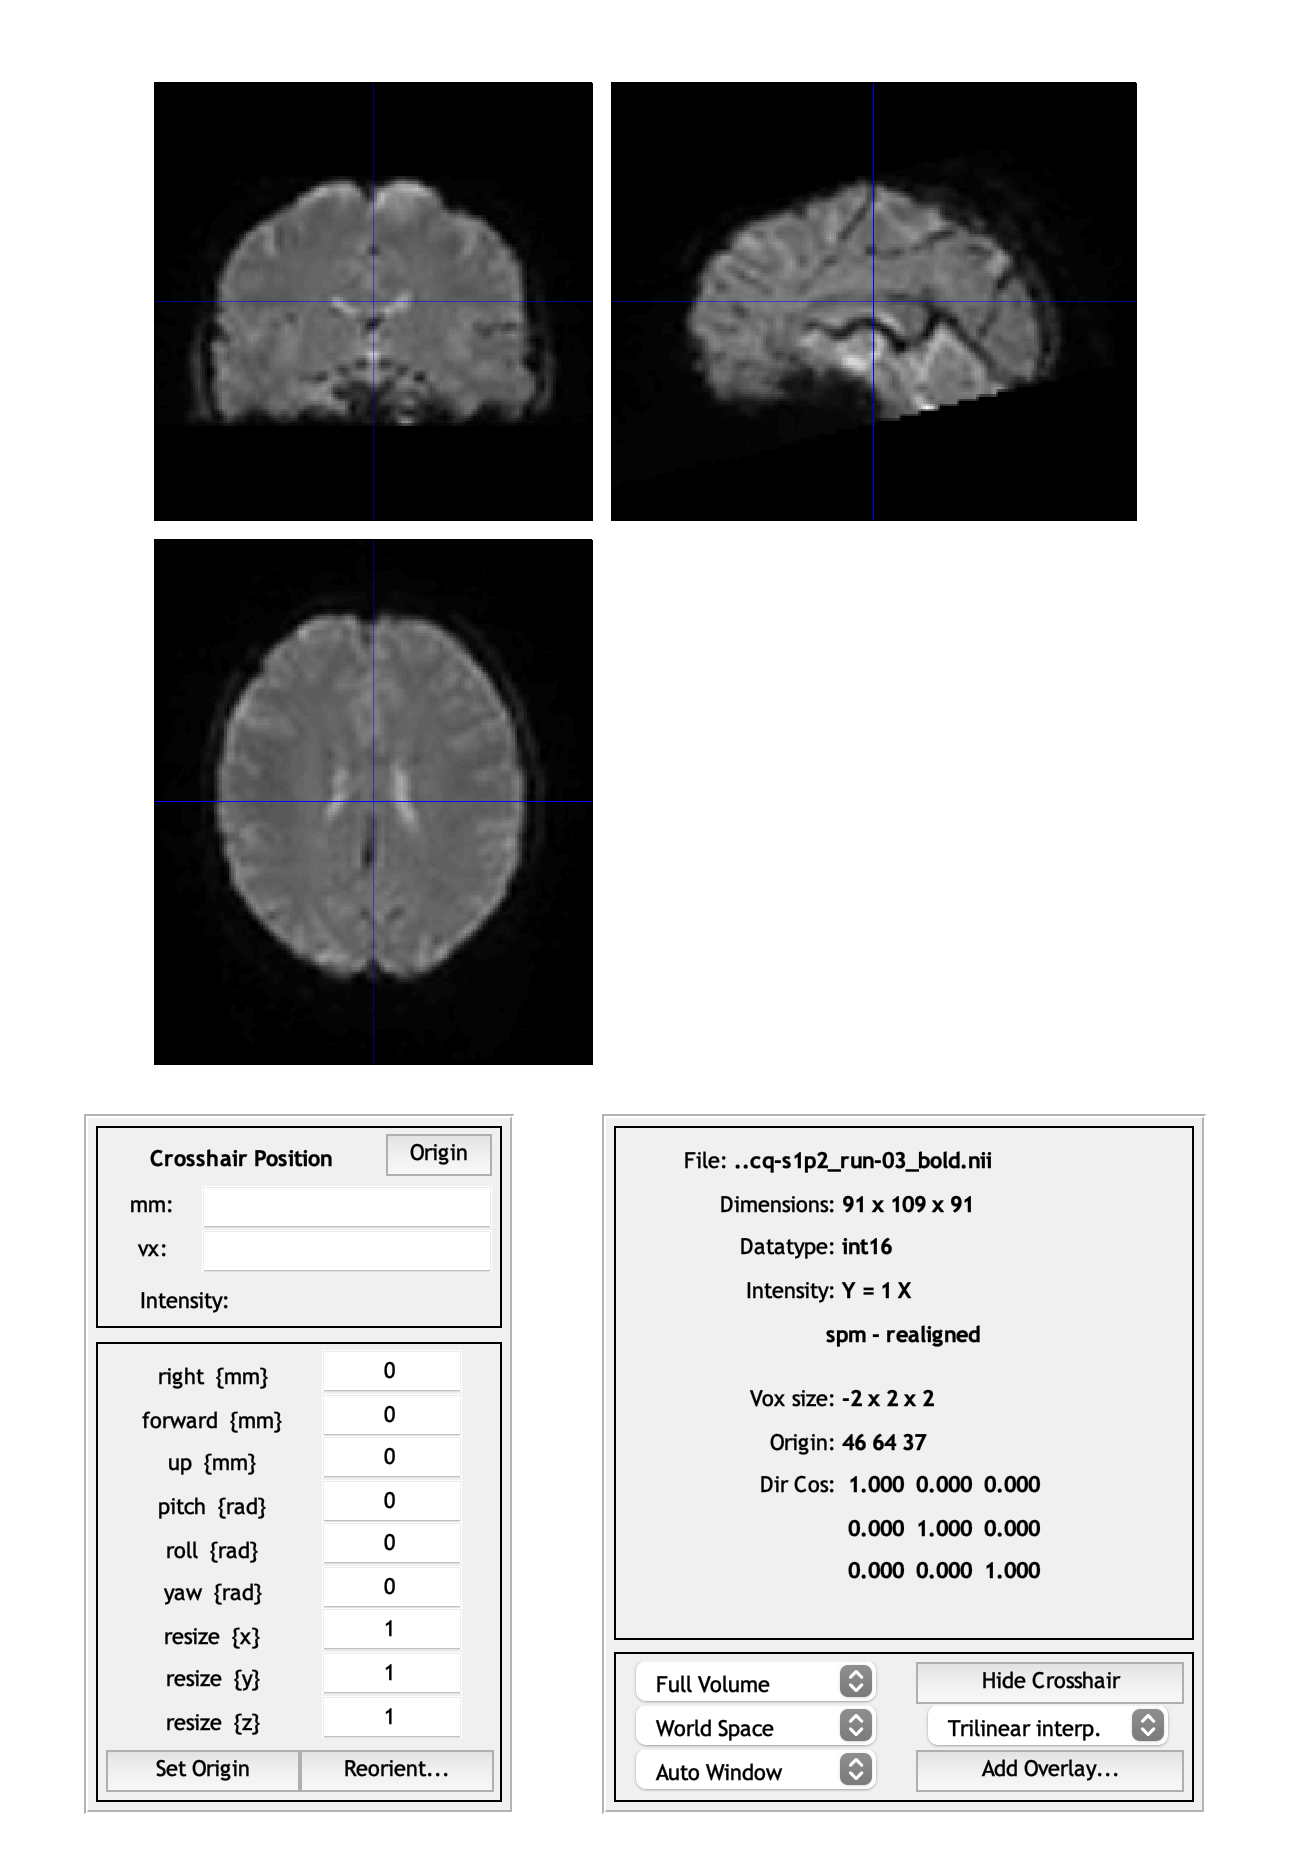

gunzip *.nii.gz

#### Display an image

Display a functional image by pushing the "Display" button, and then selecting a file. When selected, it'll appear in the bottom pane of the file selector. Hit "Done" to display the image. This brings up the SPM **orthviews**, a great way to surf around single images. 

You can also run the code below:

spm_image('init', 'rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii')

#### Questions to answer:

Where is the origin? (zero point)? Is it in the right place, at the anterior commissure? Try setting it - click and press "Set origin". When you've done that, hit "reorient" and select the image name to save to disk.

#### Coregister T1s and functional images

#### Check registration of functional and T1 images

A feature of SPM is that we need to put ,1 after .nii for the first volume of a 4-D image, ,2 for the second volume, etc.

anat = 'sub-sid001567_acq-MPRAGE_T1w.nii';
func = 'rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii,1';
spm_check_registration(char(anat, func))

% You can also use CANlab tools to display the functional over the
% structural image. 

rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii,1
Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971700 bytes
Loading image number:     1
Elapsed time is 0.056755 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.


dat1 = fmri_data(func);

Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


orthviews(dat1, 'overlay', anat, 'trans')

% A fancier version "cleans up" the functional by plotting only the top 25%
% of values:
% desc = descriptives(dat1);
% dat1 = threshold(dat1, [desc.prctile_vals(5) Inf], 'raw-between');
% orthviews(dat1, 'overlay', anat)

#### Questions to answer:

Are the images approximately lined up?  If not, set the origin for the anatomical as above. Re-plot them.

### Coregister the T1

Now we can coregister the T1 to the functional images, using "Coregister". When we "estimate", we derive a set of parameters that aligns the images, in this case with rigid-body rotation and translation. When we "reslice" we write out images, interpolating the data onto a new voxel grid.  Even if we don't reslice, SPM estimates a transformation matrix and saves in with the image, so we don't need to reslice here. 

Choose the "target" image to be the functionals, since it's more work to move a bunch (150) of functional images to the T1 rather than the reverse. Choose the "Source", the image we're moving, to be the T1. 

### 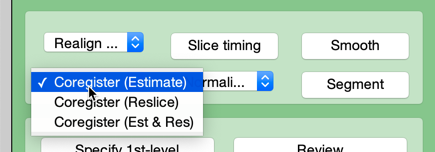

We get something like this:

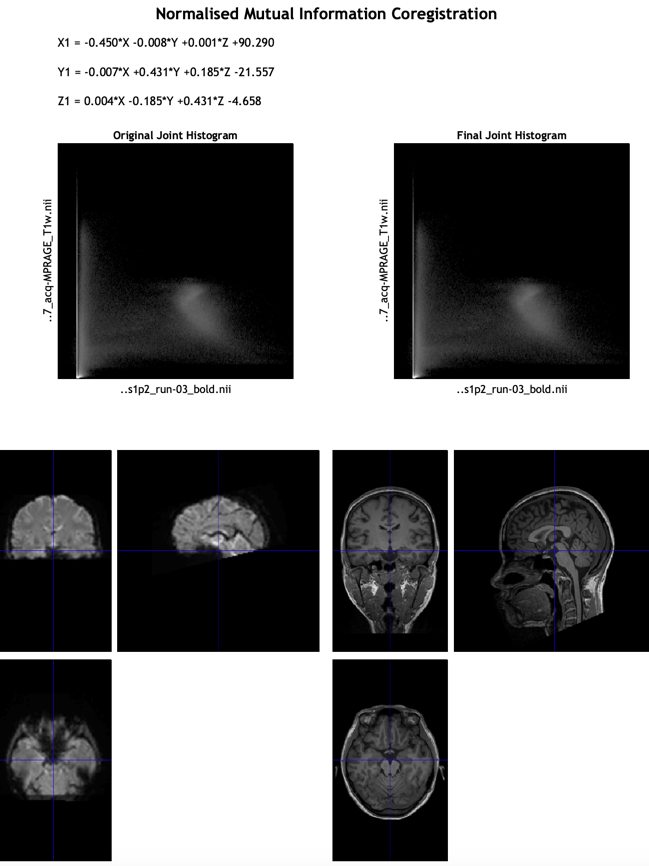

Check afterwards with:

spm_check_registration(char(anat, func))

### Normalize the images to MNI space

#### Norrmalize the T1

Start by normalizing the anatomical to MNI space. This is done with the** "Segment" **button, which segments tissue classes (gray/white/CSF) and normalizes (warps) them to standard space all in one step. This is accomplished within the algorithm by rigid body registration and alternating tissue segmentation and warping of each tissue class (c1, c2, c3, etc., where these are gray matter, white matter, and CSF, respectively) to a set of prior template maps specifying the probability that each voxel belongs to each tissue class. The result is a set of posterior probability maps for each tissue class, written out in MNI space (if you request this), along with a set of warping parameters.   

Select write Deformation Fields: Forward

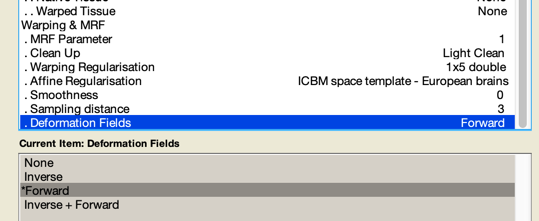

This writes several fles, depending on which you select:

`y_sub-sid001567_acq-MPRAGE_T1w.nii`

...is a forward deformation field, a "warping" or "normalization" parameter file that you can apply to other images in register with this one to normalize them to standard MNI space as well.

If you choose to write out normalized images for each tissue class, you'll get images like this one:

`mwc1sub-sid001567_acq-MPRAGE_T1w.nii`

*m is modulated, preserving the total tissue volume (see help in SPM batch editor for more details)*

*w is warped to MNI space*

*c1 is tissue class 1, gray matter [by default]*

*c2 is white matter [by default]*

*c3 is cerebrospinal fluid, CSF  [by default]*

*T1w is our name for a T1-weighted (anatomical) image.*

Check the normalization by overlaying the segmented gray matter (c1) images 

anatc1 = 'mwc1sub-sid001567_acq-MPRAGE_T1w.nii'; % m is modulated, w is warped to MNI space

Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 2304376 bytes
Loading image number:     1
Elapsed time is 0.031451 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.


dat_a = fmri_data(anatc1);

 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
Voxels: 576094	Nonempty: 513359	Complete: 513359
Unique data values: 506438
 
Min: 0.000	Max: 0.905	Mean: 0.384	Std: 0.280
 
    Percentiles      Values  
    ___________    __________

        0.1        1.0053e-06
        0.5        9.8071e-06
          1        2.8216e-05
          5          0.000521
         25          0.077914
         50            0.4223
         75           0.65562
         95            0.7496
         99           0.79223
       99.5           0.80496
       99.9           0.82998

 


desc = descriptives(dat_a);

Keeping vals between 0.078 and Inf: 385019 elements remain


dat_a = threshold(dat_a, [desc.prctile_vals(5) Inf], 'raw-between'); % keep values above 0.5, or 50% gray-matter

Grouping contiguous voxels:  56 regions


ans = 1×1 cell array
    {1×56 region}


orthviews(dat_a)


#### Normalize the functional images

Now we can apply the resulting warping to the functional images. We select the normalization parameter file `'y_sub-sid001567_acq-MPRAGE_T1w.nii'`for the deformation field, and the functional images for the "images to write". 

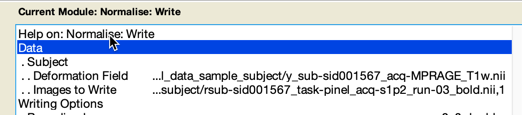

Note: you must enter ALL the frames in the "frames" window. In the file list, the "frames" are individual 3-D volumes, and these are shown with ,1 ... ,2 ... ,3 , etc, where these are the frame numbers.

The result will have a "w" prepended to it to denote "warped".  You can look at the list of files starting with "w", and *when* they were created, like this:

ls -lt w*

Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 145720800 bytes
Loading image number:   150
Elapsed time is 1.459901 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
.fullpath should have image name for each image column in .dat
Attempting to expand image filenames in case image list is unexpanded 4-D images


Let's have a look at the normalized functional images and see how they match up with an MNI-space anatomical template -- here, the standard underlay image in the* plot( )* method in CANlab tools:

Calculating mahalanobis distances to identify extreme-valued images
...based on union of corr...Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.00%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 3 4 5 6 7 

...and cov...Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 3 4 5 6 7 

done.
Outliers:
Outliers after p-value correction:
Image numbers: 1 

Image numbers, uncorrected: 1 3 4 5 6 7 


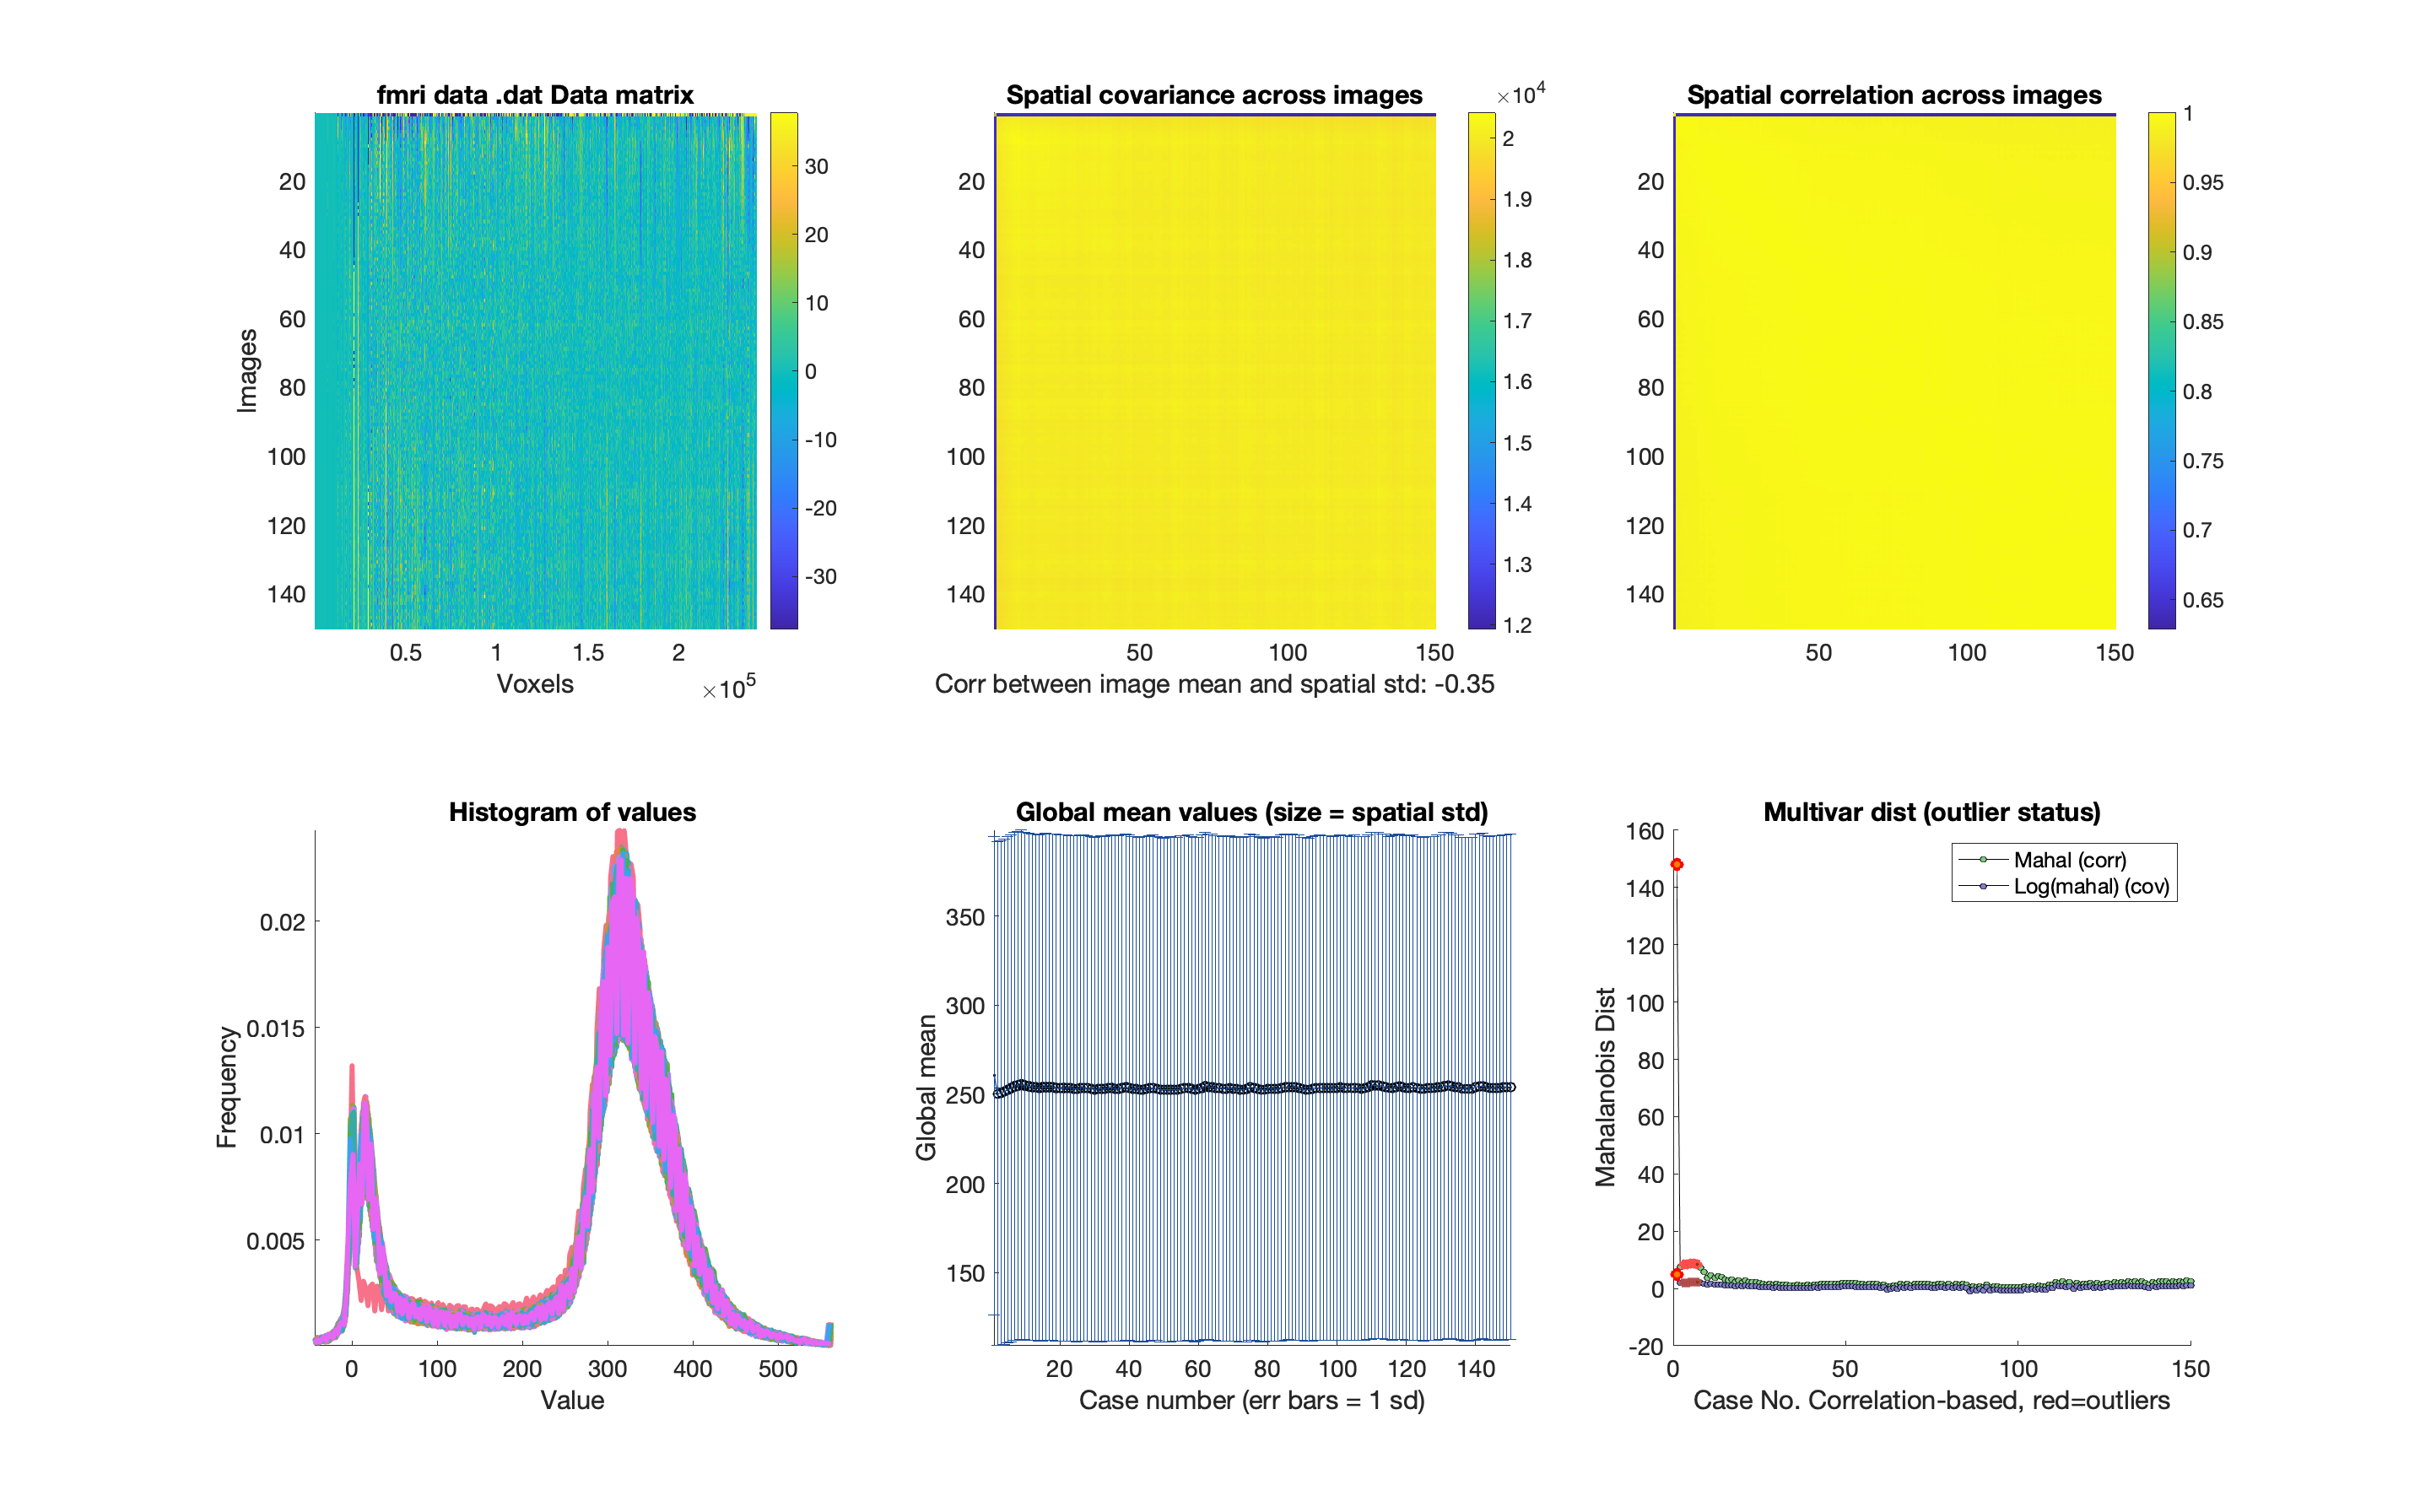

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


ans = 150×1 logical array
   1
   0
   1
   1
   1
   1
   1
   0
   0
   0


dat = fmri_data('wrsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii');

plot(dat)


#### Command line

The SPM12 interface uses the SPM batch "matlabbatch" system to define "jobs".  A job is defined by a structure with a series of fields that specify its type and options.  Estimate normalization and write normalization are passed from the GUI to the job manager, which runs the function *spm_run_norm( ) *with the specified options. 

You can save a series of jobs you build in the GUI in a .mat file.  You can then re-load them to run them later, or pass the job structure into spm_jobman( ) directly to run it.

When building your own scripts to run on many subjects, you can create job structures directly. 

*Note*: There are older ways of doing normalization in SPM12. e.g., *spm_write_sn( ) *is an older function.

#### Make a montage plot showing both the normalized gray-matter and mean functional

We can also see how both the gray-matter image (c1) and the mean functional image line up with each other and the standard MNI template. 

It's always important to look at the data on an individual-person level to assess quality. Automated coregistration and normalization algorithms can sometimes fail, producing artifacts and even nonsensical results. 

- If your functional images don't line up well with the template space (MNI), they will yield incorrect inferences about the anatomical locations of findings. 

- If coreg and warping performance is not consistent across participants, you will end up with outliers, low power, and sometimes artifactual findings.

The plot below is thus a useful diagnostic plot, which can be saved for each participant in an HTML report for each participant and examined. Other, related plots can assess registration and overlap (e.g., in gray-matter locations) across all participants in a sample as well. 

anatc1 = 'mwc1sub-sid001567_acq-MPRAGE_T1w.nii'; % m is modulated, w is warped to MNI space
dat_a = fmri_data(anatc1, 'noverbose');
desc = descriptives(dat_a);

 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
Voxels: 576094	Nonempty: 513359	Complete: 513359
Unique data values: 506335
 
Min: 0.000	Max: 0.905	Mean: 0.384	Std: 0.280
 
    Percentiles      Values  
    ___________    __________

        0.1        1.0053e-06
        0.5        9.8071e-06
          1        2.8216e-05
          5          0.000521
         25          0.077914
         50            0.4223
         75           0.65562
         95            0.7496
         99           0.79223
       99.5           0.80496
       99.9           0.82998

 


dat_a = threshold(dat_a, [desc.prctile_vals(5) Inf], 'raw-between'); % keep values above 0.5, or 50% gray-matter

Keeping vals between 0.078 and Inf: 385019 elements remain



mean_func = mean(dat);  % create a mean image
desc = descriptives(mean_func);

 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
Voxels: 242868	Nonempty: 227499	Complete: 227499
Unique data values: 62616
 
Min: -69.620	Max: 674.640	Mean: 270.638	Std: 128.969
 
    Percentiles    Values 
    ___________    _______

        0.1        -37.887
        0.5         -14.36
          1        -5.1104
          5         8.9398
         25         241.89
         50         313.18
         75         350.57
         95         414.27
         99         482.52
       99.5         509.59
       99.9         559.03

 


mean_func = threshold(mean_func, [desc.prctile_vals(4) Inf], 'raw-between'); % keep values above 25% of the mean value

Keeping vals between 8.940 and Inf: 216124 elements remain



o2 = canlab_results_fmridisplay([], 'multirow', 2);

Setting up fmridisplay objects


o2 = addblobs(o2, dat_a, 'color', [0 1 0], 'trans', 'wh_montages', 1:2);

Grouping contiguous voxels:  56 regions
sagittal montage: 10405 voxels displayed, 374614 not displayed on these slices


axial montage: 58956 voxels displayed, 326063 not displayed on these slices


o2 = title_montage(o2, 2, 'Participant gray matter 50 percent+ in green');

o2 = addblobs(o2, mean_func, 'trans', 'wh_montages', 3:4);

Grouping contiguous voxels:  11 regions
sagittal montage: 7782 voxels displayed, 208342 not displayed on these slices


axial montage: 47460 voxels displayed, 168664 not displayed on these slices


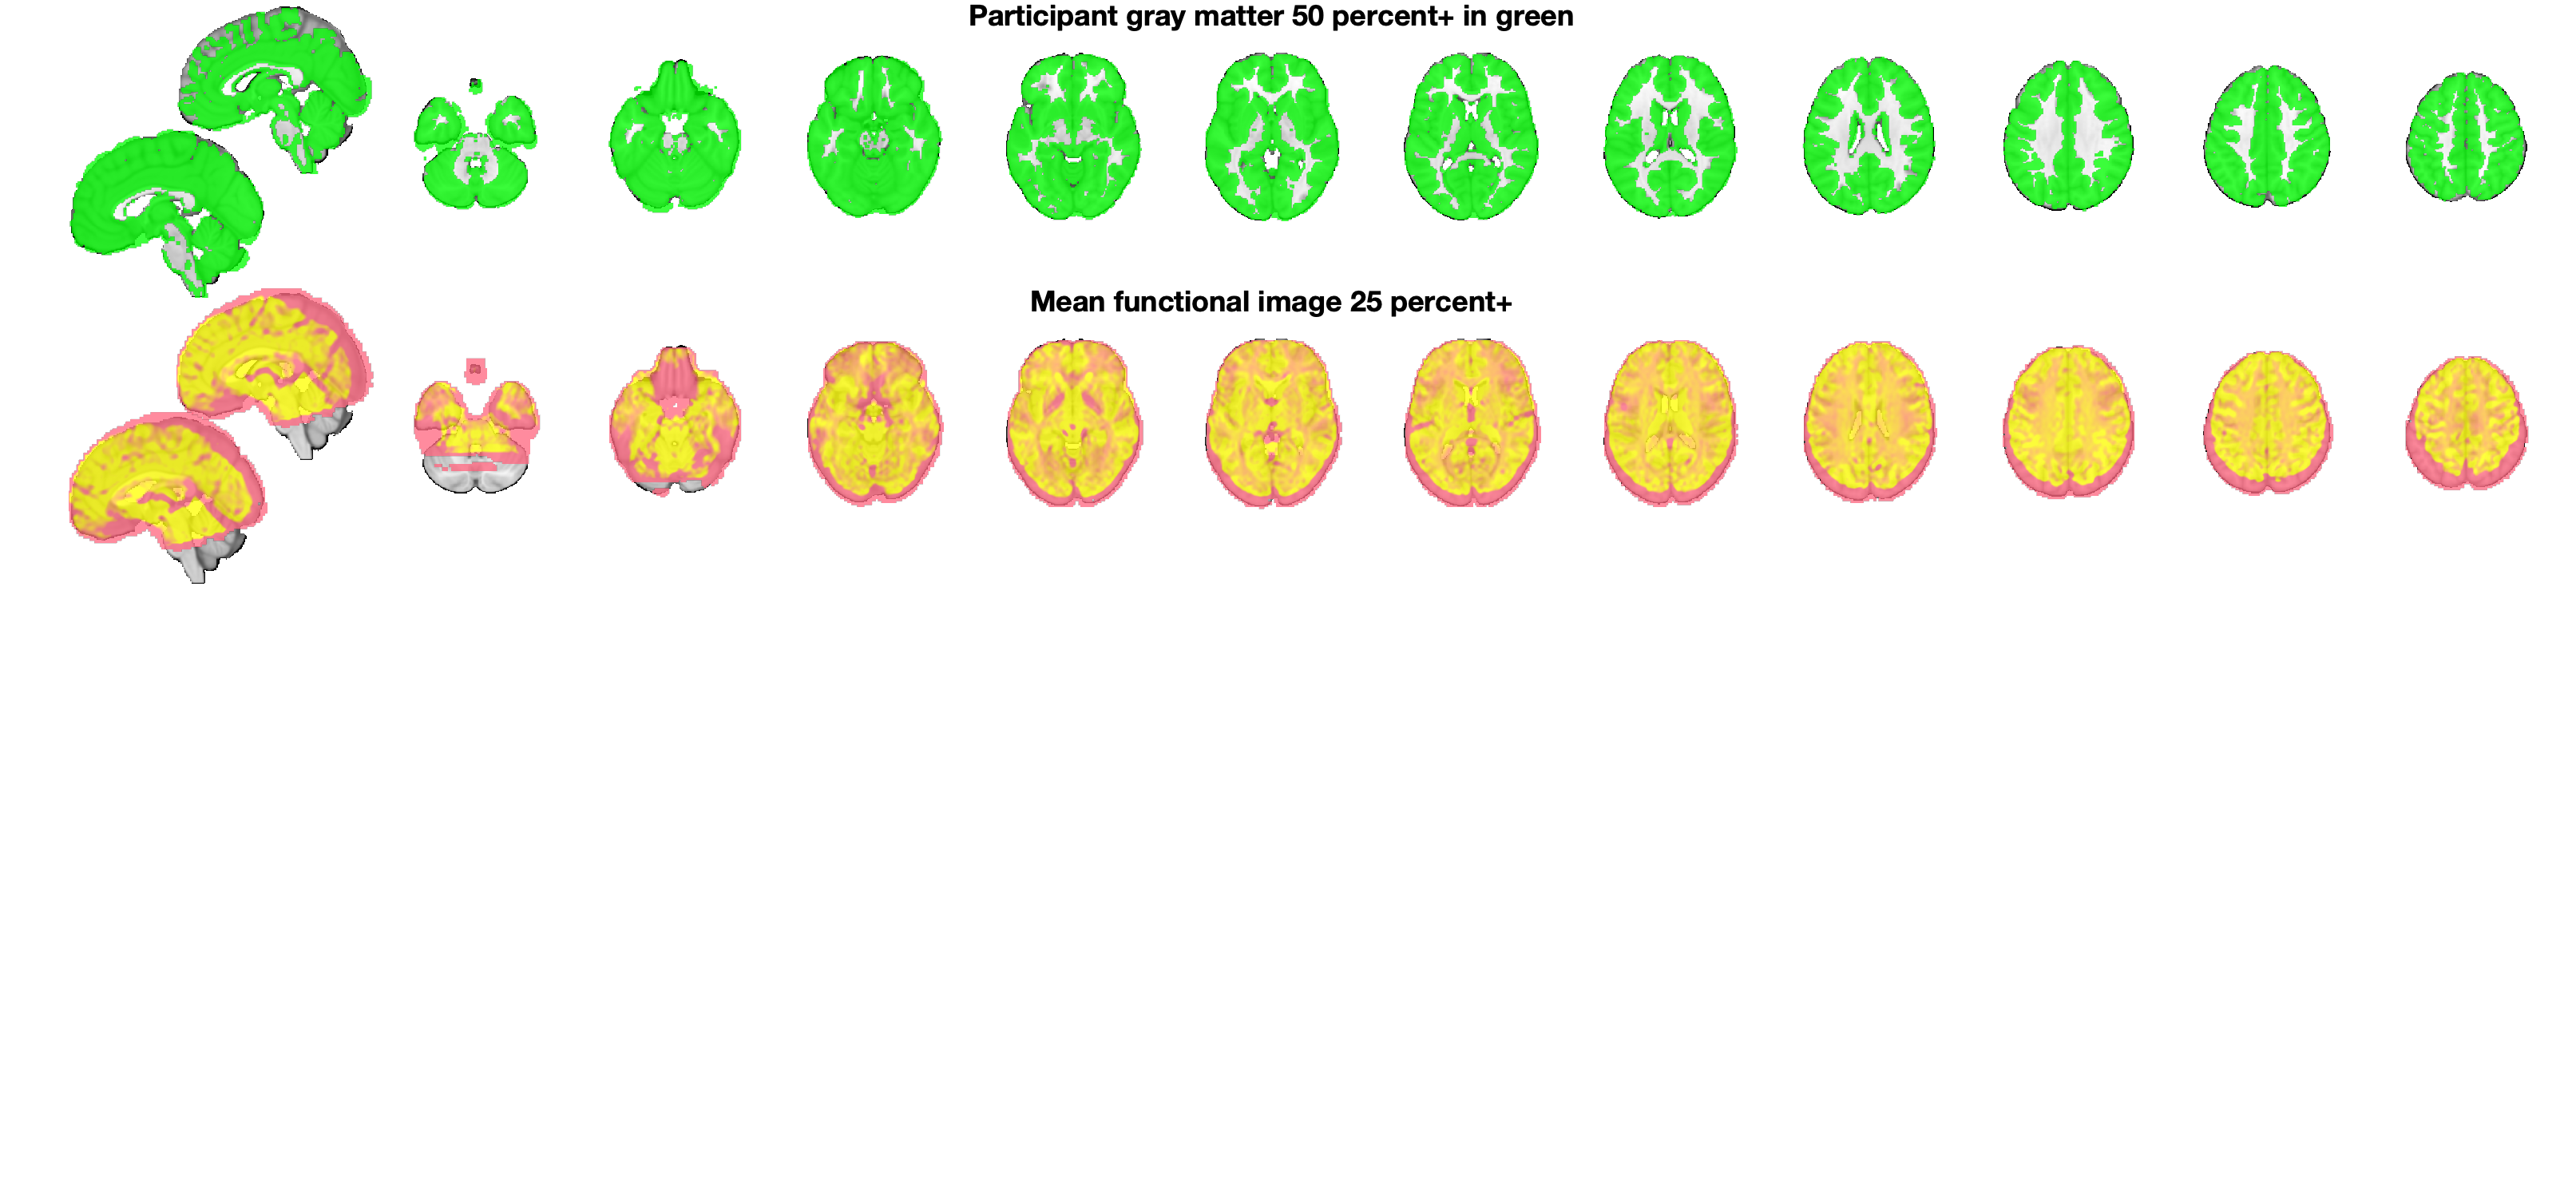

o2 = title_montage(o2, 4, 'Mean functional image 25 percent+');

### Smoothing

After normalization, the next and final stage is smoothing the functional images.

Note: you must enter ALL the frames in the "frames" window. In the file list, the "frames" are individual 3-D volumes, and these are shown with ,1 ... ,2 ... ,3 , etc, where these are the frame numbers.

You can also use the "Filter" to select only the wr* images:

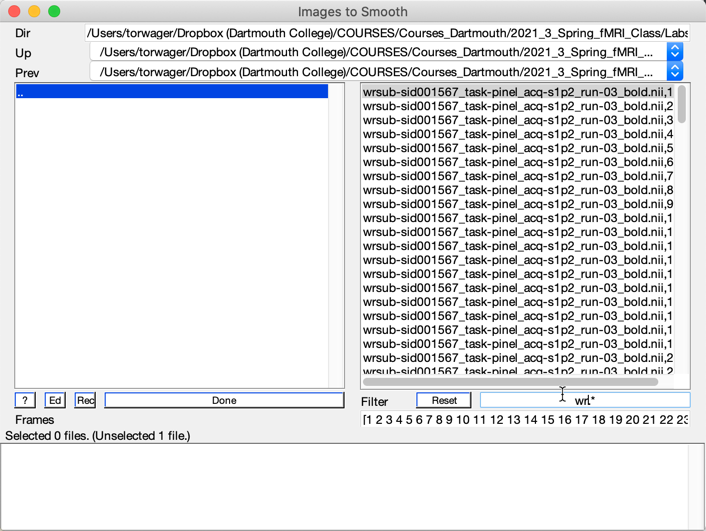

Afterwards, load and check:

preprocessed_image_name = 'swrsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii';
dat = fmri_data(preprocessed_image_name);
plot(dat);

**Zip files we don't need to clean up**

It's good practice to keep files gz'd to save space.

gzip sub-*nii
gzip rsub-*nii
gzip wrsub-*nii